# Sistemas Realimentados - 2024/1

## Nome: Arthur Lorencini Bergamaschi

## Data limite para entrega: 14/5

**Trabalhos atrasados: a nota é multiplicada por **$e^{-h/48}$**,onde h são as horas de atraso.**

**Entrega no link do google class em formato PDF!**

## Trabalho 1 - O método do lugar das raízes e projeto de PID via LR

## [Veja aqui seu valor de I](https://drive.google.com/file/d/1MvUXoYSmJgHgtbhbMUoFQAdQeph2qxkP/view?usp=sharing)

I=2 % Coloque seu valor de I

I = 2

[g1,g2,g3,g4]=init1(I);
datetime('now')

ans = datetime
   14-May-2024 23:20:36


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


**Atividade 1: Esboçar o lugar das raízes de 1+KG1(s)=0 para K>0 e K<0. Desenhe à mão, usando as propriedades de construção do LR, digitalize e coloque abaixo. Incluir no esboço:**

1.1 Raizes para $K=0$ e $K\longrightarrow \infty$.

1.2 Pontos de passagem no eixo imaginário se houver.

1.3 As assintotas e seus ângulos.

1.4 Ponto de interseção das assíntotas

1.5 Localização dos pontos de raízes múltiplas (encontro de polos)

g1

g1 =
 
  s^2 + 2 s + 0.75
  ----------------
        s^3
 
Continuous-time transfer function.
Model Properties


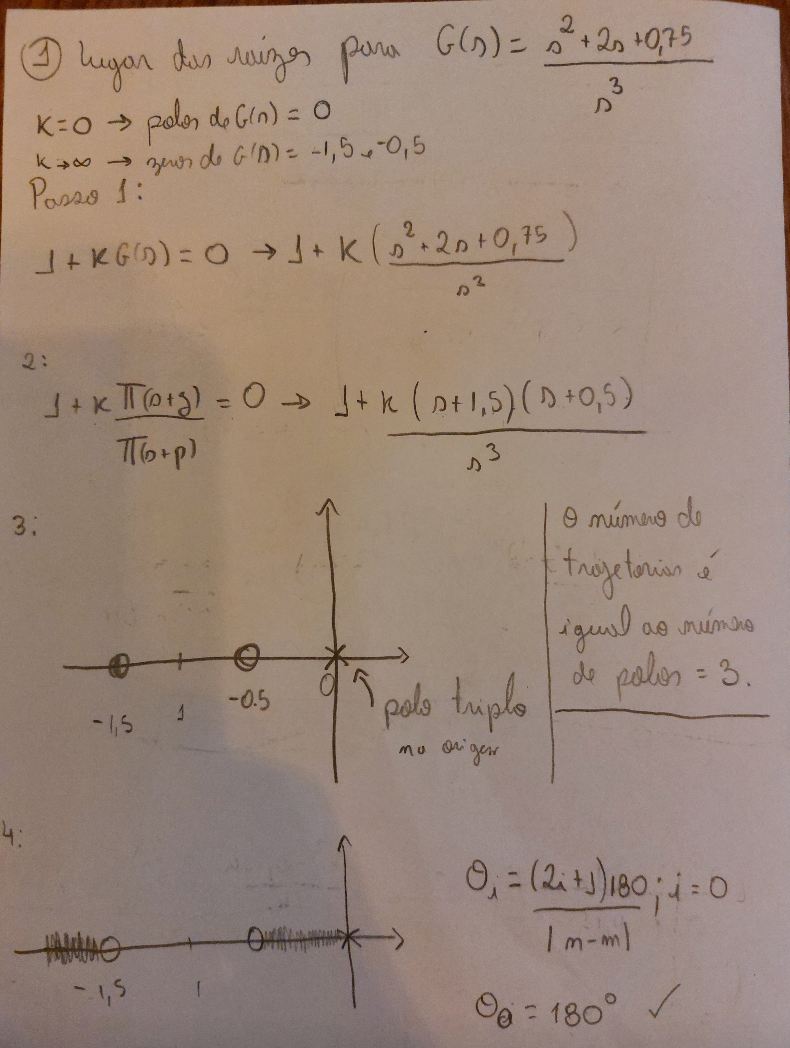

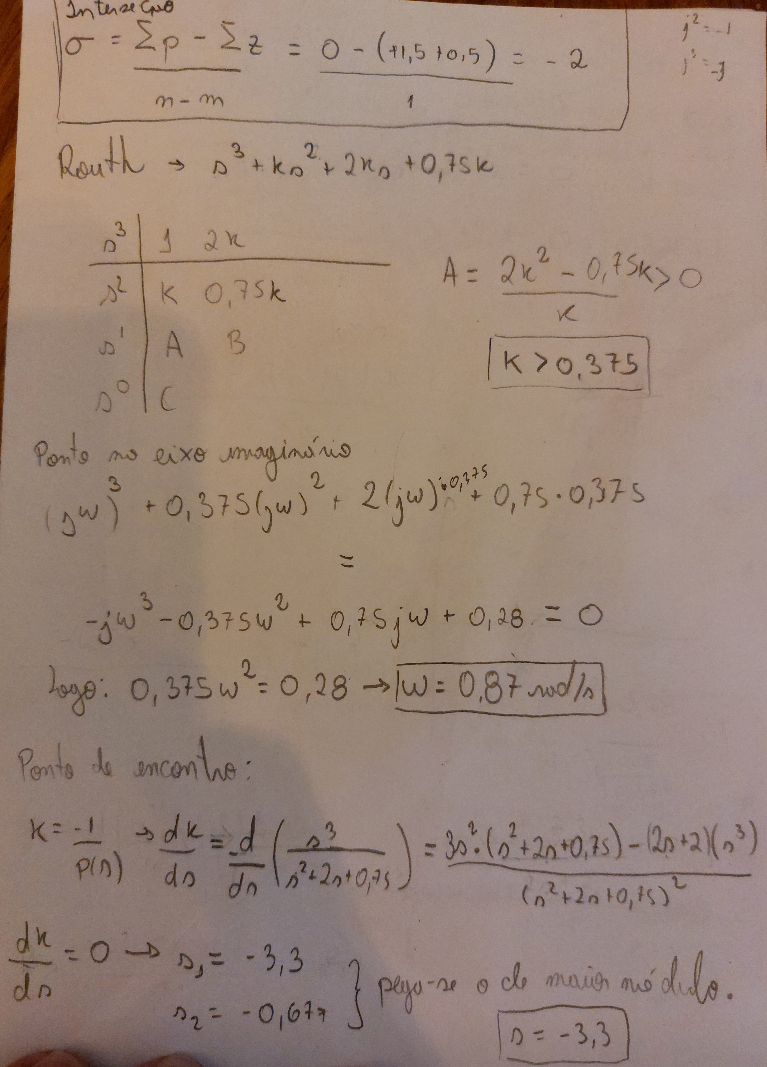

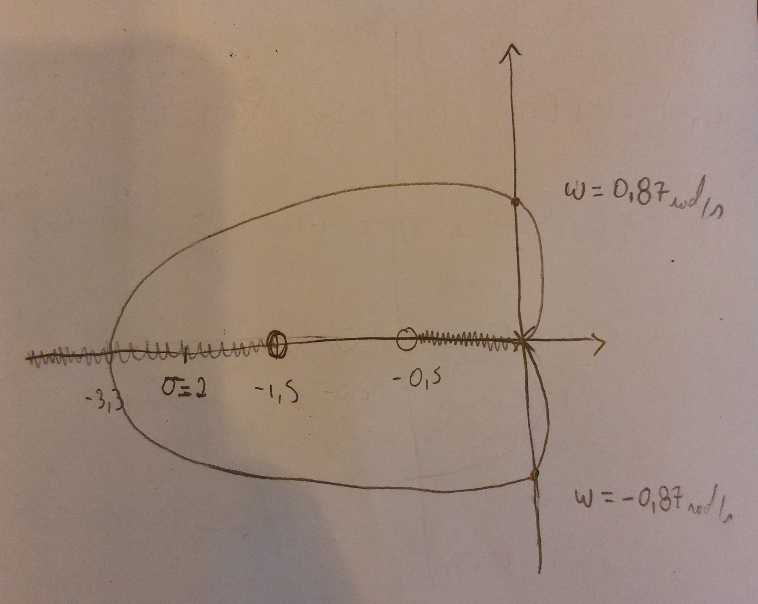

**Atividade 2: Seja o LR de 1+KG2(s)=0 mostrado. Responder as perguntas abaixo, obtendo as informações aproximadas da figura:**

**2.1 **Quais são os polos e zeros de G2(s)?

Os polos estão em -1 (duplo), -4 e o zero está em -4.8. (Utilizei uma régua no monitor)

**2.2** Quais são as raízes quando $K=0$ e $K\longrightarrow \infty$?

G_aprox = $G_{\textrm{aprox}} =\frac{\left(s+4\ldotp 8\right)}{\left(s+1\right)²\cdot \left(s+4\right)}$. Para K = 0, as raízes são os pólos de G, ou seja, -1 e -4. Para K→Inf, temos os zeros de G, ou seja, -4.8.

**2.3** Para que valores de K esse sistema é estável?

Ao analisar o K>0, vemos que o sistema é estável para todo K>0, pois as raízes não passam no semiplano direito do plano complexo.

**2.4** Para que valores de K o par de polos complexos tem amortecimento $\zeta\geq0.707$?

Vemos que a fase do ponto P que cruza o LR com a reta do amortecimento é de +/- 45º (pois $\beta =\textrm{acos}\left(0\ldotp 707\right)$). Visualmente, o ponto P tem a sua parte real em 0.9. Como a sua fase é 45º, então a parte imaginária também é 0.9. Logo P = -0.9 +/- j0.9. Sabendo que K tem a seguinte fórmula, podemos calcular para s = P.

$|K|=\frac{|s+1|²\cdot |s+4|}{|s+4\ldotp 8|}$ para s = -0.9 +/- j0.9. Logo, K = 0.66.

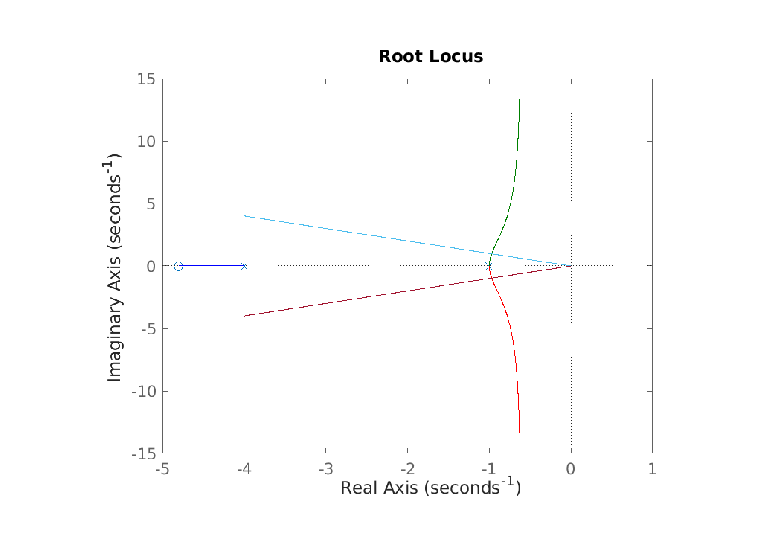

imshow('fig2.png');

**Atividade 3: Seja a FT g3(s). Projete via LR um controlador PI tal que a sobreelevação seja menor que 5%, o tempo de estabelecimento seja o menor possível e o erro em regime ao degrau seja nulo.**

- Mostre o LR utilizado para a escolha do ganho Kp.

- Mostre a resposta ao degrau em malha fechada.

- Explique como escolheu a localização do zero do PI para reduzir o tempo de estabelecimento.

Dica: relação UP com $\zeta$: $a=log(UP/100)$ , $\zeta=\sqrt{\frac{a^2}{pi^2+a^2}}$ 

g3

g3 =
 
                    1
  -------------------------------------
  s^4 + 28 s^3 + 253 s^2 + 870 s + 1008
 
Continuous-time transfer function.
Model Properties


Como queremos que o tempo de estabelecimento seja o menor possível, um bom palpite para escolher o zero do PI é colocar mais a esquerda possível, conforme o slide apresentado em aula. Vamos colocar em -15 o zero do PI e o pólo na origem (integrador)

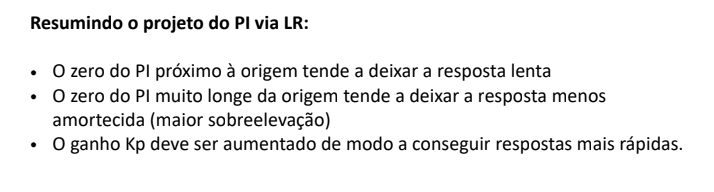

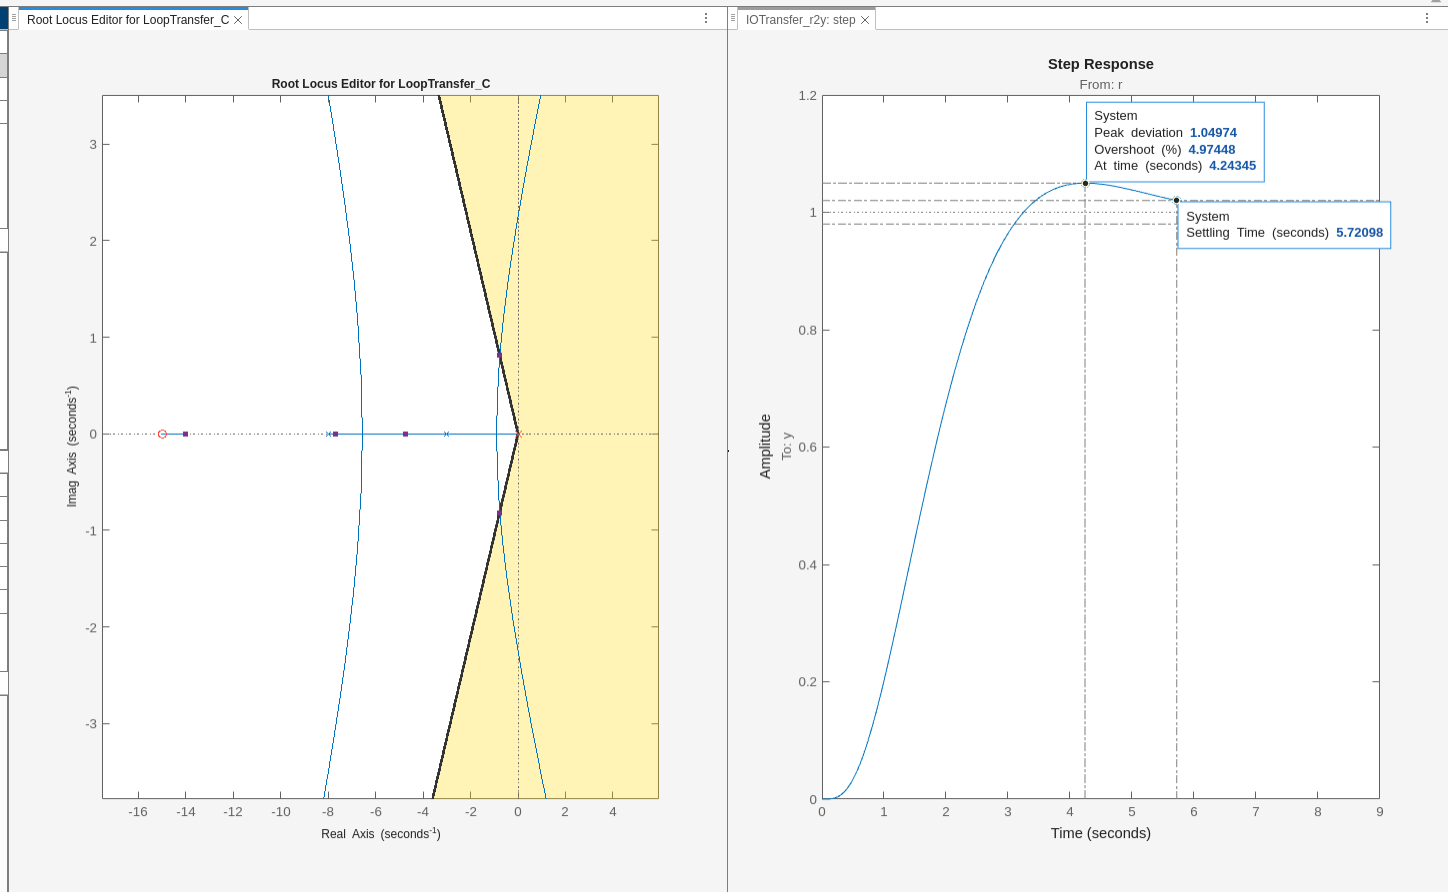

Ajustando o ganho ki para 624.2, temos que:

ki_3 = 642.2;
c_3 = ki_3*(1+0.067*s)/s;
m_3 = feedback(c_3*g3,1);
kp_3 = ki_3*0.067

kp_3 = 43.0274

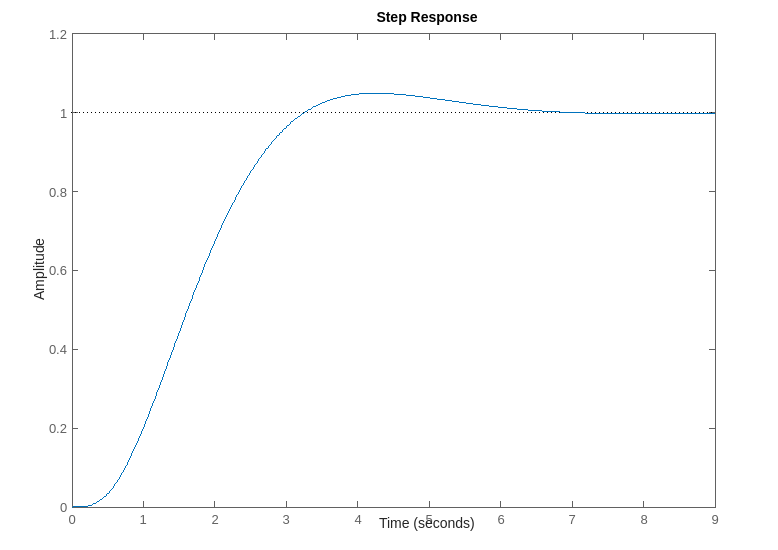

step(m_3)

**Atividade 4: Seja a FT g4(s). Projete via LR um controlador PD tal que a sobreelevação seja menor de 20%,  o tempo de estabelecimento seja o menor possível e o erro em regime ao degrau seja nulo.**

- Mostre o LR utilizado para a escolha do ganho Kd explicitando o valor de Kp utilizado.

- Mostre a resposta ao degrau em malha fechada.

- Explique como escolheu o ganho Kp para reduzir o tempo de estabelecimento.

- O par de polos complexos é dominante na resposta?Explique usando os gráficos gerados.

g4

g4 =
 
       2
  -----------
  s^3 + 2 s^2
 
Continuous-time transfer function.
Model Properties


É notório perceber que temos 2 pólos na origem e outro em -2, ou seja, kp > 0 implica em sistema instável. .O primeiro passo é fazer o LR do KP e escolher o valor de kp. Vamos escolher Kp = 0.5. e ver o LR para o KD. Com isso, ao variar o kd no LR, vemos qual vai dar a melhor resposta. Depois, nós ajustamos o valor de Kp e chegamos se está tudo certo.

Logo, temos Kd = 1.2 e Kp = 0.03

c = 1.2*s + 0.03;